clear
clf
newcolor = [228 26 28
            55 126 184
            77 175 74
            152 78 163
            255 127 0]/255

newcolor =     0.8941    0.1020    0.1098
    0.2157    0.4941    0.7216
    0.3020    0.6863    0.2902
    0.5961    0.3059    0.6392
    1.0000    0.4980         0


colororder(newcolor);

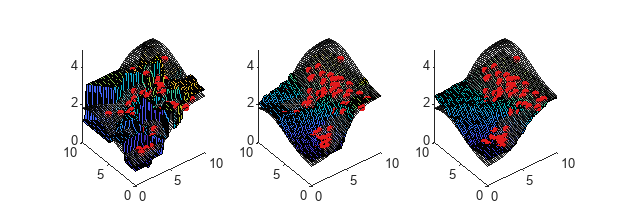

rng(2)
fig = figure(); 
fig.Position(3:4) = [900, 300];
N = 80;
fz = @(x) 2 + tanh(0.5*(x(:,1)-5)) + exp(-(x(:,2) - 8).^2/20);

NG = 50;
[xG, yG] = meshgrid(linspace(0,10,NG));
zG = reshape(fz([reshape(xG,[],1), reshape(yG,[],1)]), NG, []);

for i = 1:20
    X = [mvnrnd([2;3], [2, 0.1; 0.1, 2.5], N/2);
         mvnrnd([4;1], [1, -0.5; -0.5, 2], N/4);
         mvnrnd([0;0], [0.5, 0; 0, 0.5], N/4);] + [3 2];
    z = fz(X) + 0.5*randn(N,1);
    
    
    Nk = 50;
    [xk, yk] = meshgrid(linspace(0,10,Nk));
    
    subplot(1,3,1)
    K = 1;
    zk = reshape(kNN([reshape(xk,[],1), reshape(yk,[],1)], X, z, K), Nk, []);
    
    hold off
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    surf(xk, yk, zk)
    axis([0 10 0 10 0 5]); %axis square

    subplot(1,3,2)
    K = 10;
    zk = reshape(kNN([reshape(xk,[],1), reshape(yk,[],1)], X, z, K), Nk, []);
    
    hold off
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    surf(xk, yk, zk)
    axis([0 10 0 10 0 5]); %axis square

    subplot(1,3,3)
    K = 20;
    zk = reshape(kNN([reshape(xk,[],1), reshape(yk,[],1)], X, z, K), Nk, []);
    
    hold off
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    surf(xk, yk, zk)
    axis([0 10 0 10 0 5]); %axis square

    drawnow
end

function y = kNN(x, xData, yData, K)
    D = pdist2(x, xData);
    [~, I] = sort(D, 2);
    for i = 1:length(x)
        y(i) = mean(yData(I(i, 1:K)));
    end
end